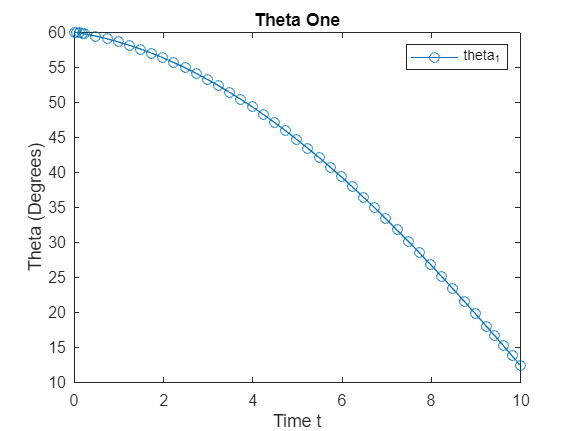




[t,theta] = ode45(@SecondODE,[0 10],[60; -1]);

figure
plot(t,theta(:,1),'-o')
title('Theta One');
xlabel('Time t');
ylabel('Theta (Degrees)');
legend('theta_1')

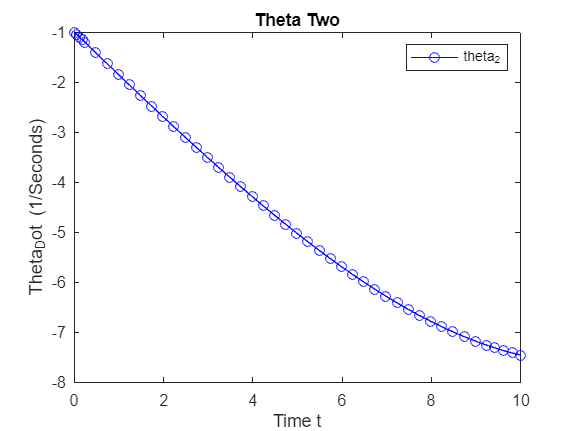


figure
plot(t,theta(:,2),'-o', 'color', 'b')
title('Theta Two');
xlabel('Time t');
ylabel('Theta_Dot (1/Seconds)');
legend('theta_2')

function state_x = SecondODE(t,x)
    state_x = [x(2); -1*sind(x(1))];
end